% === Configurações ===ptselecao
clc;
clear;
close all;
pause(2);

% === Constantes ===
h_padrao = 0.5;
h_gripper = 0.155 - 0.018; % correção devido à altura do gripper
pos_padrao = [0,pi,0,0, -0.5, h_padrao];
ang_padrao = [1.2915, -1.5708, 1.5708, -1.5708, -1.5708, 0.0000];

UR5 = urRTDEClient('192.168.1.10','CobotName','universalUR5e')

UR5 =   urRTDEClient with properties:

            CobotName: 'universalUR5e'
       URControllerIP: '192.168.1.10'
    ControllerVersion: '5.22.0.0'
        RTDEFrequency: 125
    ConnectionTimeOut: 10
        RigidBodyTree: [1×1 rigidBodyTree]


realSense = realsenseSubscriberSO_ARM;
Detector = load("DetectorARMChallenge2.mat").Detector1;

% Branca 

% Lata 1
pos = [0.219, -0.318, 0.4];
rot = 0;
pegar(pos,rot,UR5)
lixo("Can",UR5)

% Spam
pos = [0.190, -0.552, 0.239];
rot = 1.18;
pegar(pos,rot,UR5)
lixo("Spam",UR5)

% Bottle 1
pos = [0.262, -0.634, 0.2];
rot = 0.8727;
pegar(pos,rot,UR5)
lixo("Bottle",UR5)

% Lata 2
pos = [-0.343, -0.078, 0.332];
rot = 0;
pegar(pos,rot,UR5)
lixo("Can",UR5)

% Lata 3
pos = [-0.343, -0.078, 0.24];
rot = 0;
pegar(pos,rot,UR5)
lixo("Can",UR5)  

% Cubo 1
pos = [-0.355, 0.031, 0.237];
rot = 0;
pegar(pos,rot,UR5)
pesar(UR5);
lixo("Red_cube",UR5);

% Cubo 2
pos = [-0.355, 0.031, 0.213];
rot = 0;
pegar(pos,rot,UR5)
pesar(UR5);
lixo("Green_cube",UR5);

% Cubo 3
pos = [-0.355, 0.031, 0.183];
rot = 0;
pegar(pos,rot,UR5)
pesar(UR5);
lixo("Blue_cube",UR5);

% Cubos

% Cubo 1
pos = [-0.086, -0.412, 0.195];
rot = 1.2915;
pegar(pos,rot,UR5)
pesar(UR5);
lixo("Blue_cube",UR5);

% Cubo 2
pos = [-0.004, -0.412, 0.195];
rot = 1.2915;
pegar(pos,rot,UR5)
pesar(UR5);
lixo("Green_cube",UR5);

% Cubo 3
pos = [ 0.070, -0.412, 0.195];
rot = 1.2915;
pegar(pos,rot,UR5)
pesar(UR5);
lixo("Blue_cube",UR5);

% Cubo 4
pos = [-0.002, -0.330, 0.195];
rot = 0;
pegar(pos,rot,UR5)
pesar(UR5);
lixo("Red_cube",UR5);

% Cubo 5
pos = [-0.082, -0.330, 0.195];
rot = 1.2915;
pegar(pos,rot,UR5)
pesar(UR5);
lixo("Black_cube",UR5);

% Cubo 7
try
    % Pos padrão
    [~,~] = sendCartesianPoseAndWait(UR5,pos_padrao,'Velocity', 0.25,'EndTime',0);
    
    %aproximar
    [~,~] = sendJointConfigurationAndWait( UR5,[1.7977, -0.3665, 0.4189, -1.6663, -1.5789, 0.1607],'Velocity', 0.25,'EndTime',0);
    
    % pegar
    pause(1)
    actuateGripper(UR5,"grip");
    pause(1);
    
    [~,~] = sendJointConfigurationAndWait( UR5,ang_padrao,'Velocity', 0.25,'EndTime',0);
    pesar(UR5);
    lixo("Black_cube",UR5);
catch ME
end

conferencia =      0     0     0     0


pos_busca =     0.0440   -0.6900    0.5000


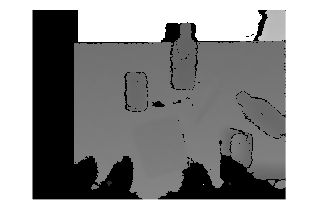

Pontos iniciais: 302510 | Após filtro: 287479
Pontos iniciais: 17157 | Após filtro: 13413
Pontos iniciais: 13315 | Após filtro: 10207
Pontos iniciais: 13230 | Após filtro: 12257
Pontos iniciais: 44941 | Após filtro: 42069
Pontos iniciais: 17157 | Após filtro: 13413
Pontos iniciais: 13315 | Após filtro: 10207
Pontos iniciais: 13230 | Após filtro: 12257


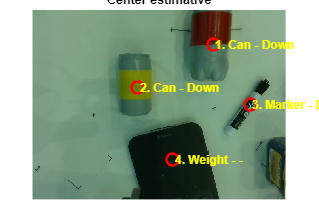


idxvarado =

  0×1 empty double column vector



sts = 4×1 categorical array
     Down 
     Down 
     Down 
     - 


labels = 4×1 categorical array
     Can 
     Can 
     Marker 
     Weight 


scores = 4×1 single column vector
    0.7748
    0.9250
    0.9228
    0.9266


     Can 
     Can 
     Marker 
     Weight 



Erro VERM 1: Unrecognized function or variable 'ptobjeto'.


% vermelho 1
try
    [~,~] = sendJointConfigurationAndWait(UR5,ang_padrao,'EndTime',10);
    pos_busca = [0.044, -0.68, 0.5];
    dzInicial = 0.05;
    minPontosInicial = 3000;
    
    conferencia = zeros(1,4) %BCSM
    while conferencia(1) <0.9 || conferencia(2) <0.9 || conferencia(4) <0.9
        pos_busca(2) = pos_busca(2) - 0.01
        [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,0,pos_busca(1),pos_busca(2),pos_busca(3)],'Velocity', 0.25,'EndTime',0);
        
        % Capturar imagem
        [colorImage, depthImage] = realSense.step;
        depthImage = depthImage(:,:,3);
        colorImage = imresize(colorImage,[480,640]);
        depthImage = imresize(depthImage,[480,640]);
        imshow(colorImage);
        imshow(depthImage);
        
        pack = cell(1,3);
        pack{1} = Detector;
        pack{2} = colorImage;
        pack{3} = depthImage;
        
        [~,~,objSem,~] = PcGenRSD435(pack);
        
        [~,idxvarado,sts,labels,scores] = ARMVision(colorImage,depthImage,Detector,0.5)

        try
            dzInicial = 0.05;
            minPontosInicial = 3000;
            

            [~, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);
        catch ME
        end
        
        for k = 1:size(sts)
            ptobjeto = objSem{k};
            if ismember(k,idxvarado)
               fprintf("varado")
            else    
                label = labels(k);
                disp(labels)
            
                % Lata 1
                if label == "Can"
                    [z1, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);
                    if sts(k) == "Up"
                        pos = [0.120, -0.736, 0.24];
                        rot = 0;
                    elseif sts(k) == "Down"
                        pos = [0.120, -0.736, 0.2];            
                        rot = Calcular_rot(ptselecao,UR5) + pi/2
                    end
                    pegar(pos,rot,UR5)
                    lixo("Can",UR5)
                    conferencia(2) = conferencia(2) + 1;
            
                 % garrafa 1   
                elseif label == "Bottle"
                    if sts(k) == "Up"
                       ang = [1.3963, -0.6109, 0.6283, -1.5882, -1.5533, -1.6406];
                       [~,~] = sendJointConfigurationAndWait(UR5,ang,'EndTime',5);
            
                        pause(1)
                        actuateGripper(UR5,"grip");
                        pause(1);
            
                       [~,~] = sendJointConfigurationAndWait( UR5,ang_padrao,'EndTime',5);
            
                    elseif sts(k) == "Down"
                        ang = [1.3963,-0.57596, 0.80285, -1.7802, -1.5533, 0];
                        [~,~] = sendJointConfigurationAndWait(UR5,ang,'EndTime',5);
            
                        pause(1)
                        actuateGripper(UR5,"grip");
                        pause(1);
            
                       [~,~] = sendJointConfigurationAndWait( UR5,ang_padrao,'EndTime',5);
                    end
                    lixo("Bottle",UR5)
                    conferencia(1) = conferencia(1) + 1;
                % Marker
                elseif label == "Marker"
                    [~, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);
                    if sts(k) == "Up"
                        pos = [-0.087, -0.700, 0.25];
                        rot = 0;
                    elseif sts(k) == "Down"
                        pos = [-0.087, -0.700, 0.195];
                        rot = Calcular_rot(ptselecao,UR5)
                    end
                        pegar(pos,rot,UR5)
                        lixo("Marker",UR5)
                        conferencia(4) = conferencia(4) + 1;
                end
            end
        end
        disp(conferencia)
    end
catch ME
    fprintf('Erro VERM 1: %s\n', ME.message);
end

conferencia =      0     0     0     0


pos =    -0.0820   -0.3200    0.1950


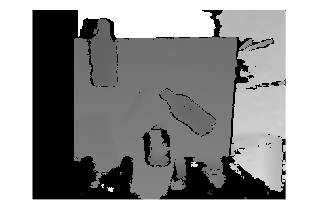

objSem = 1×3 cell array
    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}


Erro VERM 2: Unrecognized function or variable 'realHeight'.


% vermelho 2
try
    [~,~] = sendJointConfigurationAndWait(UR5,ang_padrao,'EndTime',10);
    pos_busca = [-0.17, -0.68, 0.5];
    dzInicial = 0.05;
    minPontosInicial = 3000;
    
    conferencia = zeros(1,4) %BCSM
    while conferencia(1) <0.9 || conferencia(3) <0.9
        pos(2) = pos(2) + 0.01
        [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,0,pos_busca(1),pos_busca(2),pos_busca(3)],'Velocity', 0.25,'EndTime',0);
        
        % Capturar imagem
        [colorImage, depthImage] = realSense.step;
        depthImage = depthImage(:,:,3);
        colorImage = imresize(colorImage,[480,640]);
        depthImage = imresize(depthImage,[480,640]);
        imshow(colorImage);
        imshow(depthImage);
        
        pack = cell(1,3);
        pack{1} = Detector;
        pack{2} = colorImage;
        pack{3} = depthImage;
        
        [~,~,objSem,~,~] = PcGenRSD435(pack)
        
        [~,idxvarado,sts,labels,~] = ARMVision(colorImage,depthImage,Detector,0.5)
    
        
            for k = 1:size(sts)
                if ismember(k,idxvarado)
                   fprintf("varado")
                else    
                    label = labels(k);
                        
                    dzInicial = 0.05;
                    minPontosInicial = 3000;
                    ptobjeto = objSem{k};
                
                    [~, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);
                    
                    disp(label);
                
                    % garrafa 2   
                    if label == "Bottle"
                    [~, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);
                        if sts(k) == "Up"
                            pos = [-0.230, -0.679, 0.27];
                            rot = 0;
                        elseif sts(k) == "Down"
                            pos = [-0.230, -0.679, 0.2];
                            rot = Calcular_rot(ptselecao,UR5) + pi/2
                        end  
                        pegar(pos,rot,UR5)
                        lixo("Bottle",UR5)
                        conferencia(1) = conferencia(1) +1;
                    % Spam
                    elseif label == "Spam"
                        [~, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);
                        if sts(k) == "Up"
                            pos = [0.120, -0.736, 0.24];
                            rot = 0;
                        elseif sts(k) == "Down"
                            pos = [0.120, -0.736, 0.2];
                            rot = Calcular_rot(ptselecao,UR5)
                        end
                            pegar(pos,rot,UR5)
                            lixo("Spam",UR5)
                            conferencia(3) = conferencia(3) + 1;
                    end
                end
             end
    disp(conferencia)
    end
catch ME
    fprintf('Erro VERM 2: %s\n', ME.message);
end 

conferencia =      0     0     0     0


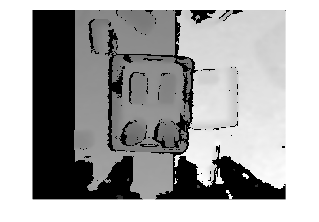

objSem = 1×8 cell array
    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}


Pontos iniciais: 292760 | Após filtro: 256606
Pontos iniciais: 5668 | Após filtro: 3449
Pontos iniciais: 1156 | Após filtro: 607
Pontos iniciais: 11060 | Após filtro: 7203
Pontos iniciais: 7287 | Após filtro: 4775
Pontos iniciais: 8351 | Após filtro: 6322
Pontos iniciais: 9721 | Após filtro: 7599
Pontos iniciais: 5613 | Após filtro: 4830
Pontos iniciais: 10877 | Após filtro: 7024
Pontos iniciais: 11060 | Após filtro: 7203
Pontos iniciais: 7287 | Após filtro: 4775
Pontos iniciais: 8351 | Após filtro: 6322
Pontos iniciais: 9721 | Após filtro: 7599
Pontos iniciais: 5613 | Após filtro: 4830
Pontos iniciais: 10877 | Após filtro: 7024


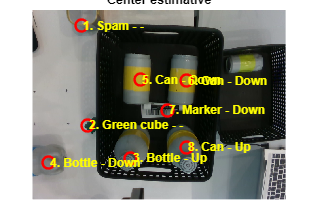

displacement = 2×8 single matrix
   -0.1940   -0.1910   -0.0556   -0.2716   -0.0448    0.0629    0.0201    0.0563
    0.1919   -0.0595   -0.1067   -0.1473    0.0546    0.0515   -0.0197   -0.0929



idxvarado =

  0×1 empty double column vector



sts = 8×1 categorical array
     - 
     - 
     Up 
     Down 
     Down 
     Down 
     Down 
     Up 


dlabels = 8×1 categorical array
     Spam 
     Green_cube 
     Bottle 
     Bottle 
     Can 
     Can 
     Marker 
     Can 


scores = 8×1 single column vector
    0.6128
    0.8316
    0.7254
    0.8304
    0.9286
    0.8530
    0.6772
    0.6454



rots =

  0×0 empty cell array



Ângulo theta dominante: 62.71 graus
Ângulo theta dominante: 94.12 graus
Ângulo theta dominante: 93.65 graus
Ângulo theta dominante: 1.08 graus


pos = 1×3 single row vector
   -0.0556   -0.1067    0.2700


pos = 1×3 single row vector
    0.0563   -0.0929    0.2400


pos = 1×3 single row vector
   -0.0448    0.0546    0.2000


rot = single
-2.4969

pos = 1×3 single row vector
    0.0629    0.0515    0.2000


rot = single
-2.5051

pos = 1×3 single row vector
   -0.2716   -0.1473    0.2000


rot = single
0.0964

Erro AZUL: Error receiving data from the remote server.
Additional Information: Operation timed out before requested data was received.


% Azul
try
    [~,~] = sendJointConfigurationAndWait(UR5,ang_padrao,'EndTime',10);

    conferencia = zeros(1,4) %BCSM
    while conferencia(1) <1.9 || conferencia(2) <1.9 || conferencia(4) <0.9
        
        pos_busca = [-0.334, -0.374, 0.6];
        [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,0,pos_busca(1),pos_busca(2),pos_busca(3)],"EndTime",10);
        
        % === Capturar imagem ===
        [colorImage, depthImage] = realSense.step;
        depthImage = depthImage(:,:,3);
        colorImage = imresize(colorImage,[480,640]);
        depthImage = imresize(depthImage,[480,640]);
        imshow(colorImage);
        imshow(depthImage);
        
        pack = cell(1,3);
        pack{1} = Detector;
        pack{2} = colorImage;
        pack{3} = depthImage;
        
        [~,~,objSem,~,~] = PcGenRSD435(pack)
          
        [displacement,idxvarado,sts,dlabels,scores] = ARMVision(colorImage,depthImage,Detector,0.6)
        
       
        % === Calcular esdados e rot ===
        rots = {}
        for i=1:size(sts)
            try
                dzInicial = 0.05;
                minPontosInicial = 3000;
                ptobjeto = objSem{i};
            
                [~, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);
                
                if sts(i) == "Up"
                    rot = 0;
                elseif sts(i) == "Down"
                    rot = Calcular_rot(ptselecao,UR5);
                end
                rots{end + 1} = rot;
            catch ME
            end 
        end
        
        % === pegar ===
        
        for i=1:size(sts)

            if ismember(i,idxvarado)
                   fprintf("varado")
                else
                if sts(i) == "Up"
                    if dlabels(i) == "Bottle"
                        pos = [displacement(1,i), displacement(2,i), 0.27]
                        pos(1) =(-0.334) - pos(1);
                        pos(2) =(-0.374) - pos(2);
                        rot = pi/2;
                        pegar(pos,rot,UR5)
                        lixo("Bottle",UR5)
                        conferencia(1) = conferencia(1) + 1;
                    end   
                end
            end
        end
        for i=1:size(sts)
            if ismember(i,idxvarado)
               fprintf("varado")
            else
                if sts(i) == "Up"
                    if dlabels(i) == "Can"
                        pos = [displacement(1,i), displacement(2,i), 0.24]
                        pos(1) =(-0.334) - pos(1);
                        pos(2) =(-0.374) - pos(2);
                        rot = pi/2;
                        pegar(pos,rot,UR5)
                        lixo("Can",UR5)
                        conferencia(2) = conferencia(2) + 1;
                    end
                end
            end
        end
        for i=1:size(sts)
            if ismember(i,idxvarado)
               fprintf("varado");
            else
                if sts(i) == "Up"
                    if dlabels(i) == "Marker"
                        pos = [displacement(1,i), displacement(2,i), 0.25]
                        pos(1) =(-0.334) - pos(1);
                        pos(2) =(-0.374) - pos(2);
                        rot = pi/2;
                        pegar(pos,rot,UR5)
                        lixo("Marker",UR5)
                        conferencia(4) = conferencia(4) + 1;
                    end
                end
            end
        end
        for i=1:size(sts)
            if ismember(i,idxvarado)
               fprintf("varado");
            else
                if sts(i) == "Down"
                    if dlabels(i) == "Can"
                        pos = [displacement(1,i), displacement(2,i), 0.2]
                        pos(1) =(-0.334) - pos(1);
                        pos(2) =(-0.374) - pos(2);
                        rot = rots{i}
                        pegar(pos,rot,UR5)
                        lixo("Can",UR5)
                        conferencia(2) = conferencia(2) + 1;
                    end
                end
            end
        end
        for i=1:size(sts)
            if ismember(i,idxvarado)
               fprintf("varado");
            else
                if sts(i) == "Down"
                    if dlabels(i) == "Bottle"
                        pos = [displacement(1,i), displacement(2,i), 0.2]
                        pos(1) =(-0.334) - pos(1);
                        pos(2) =(-0.374) - pos(2);
                        rot = rots{i}
                        pegar(pos,rot,UR5)
                        lixo("Bottle",UR5)
                        conferencia(1) = conferencia(1) + 1;
                    end
                end
            end
        end
        for i=1:size(sts)
            if ismember(i,idxvarado)
               fprintf("varado");
            else
                if sts(i) == "Down"
                    if dlabels(idxitens(i)) == "Marker"
                        pos = [displacement(i,1), displacement(2,i), 0.195]
                        pos(1) =(-0.334) - pos(1);
                        pos(2) =(-0.374) - pos(2);
                        rot = rots{i}
                        pegar(pos,rot,UR5)
                        lixo("Marker",UR5)
                        conferencia(4) = conferencia(4) + 1;
                    end
                end
            end
        end
    end
catch ME
    fprintf('Erro AZUL: %s\n', ME.message);
end

try
    % Cubo 6
    pos = [-0.139, -0.330, 0.195];
    rot = 1.2915;
    pegar(pos,rot,UR5)
    pesar(UR5);
    lixo("Green_cube",UR5);
catch ME
end

% Amarelo esquerda
try
    [~,~] = sendJointConfigurationAndWait(UR5,ang_padrao,'EndTime',10);
    % capturar imagem
    [~,~] = sendJointConfigurationAndWait(UR5,ang_padrao,'Velocity', 0.25,'EndTime',0);
    ang = [2.1118, -2.4245, 2.2325, -1.3788, -1.5656, 0.8475];
    [~,~] = sendJointConfigurationAndWait( UR5,ang,'Velocity', 0.25,'EndTime',0);
    
    % Detectar tipo
    [rgbImg,~] = realSense.step;
    [~, score, label] = detect(Detector, rgbImg);
    
    % Filtrar apenas classes desejadas
    classesPermitidas = ["Can", "Bottle"];
    isPermitido = ismember(string(label), classesPermitidas);
    
    % Aplicar o filtro de classe
    score = score(isPermitido);
    label = label(isPermitido);
    
    if ~isempty(score)
        [~, idxMax] = max(score);
        tipo = string(label(idxMax));
    else
        tipo = "Nenhum";
    end
    
    % % Vizualizar
    % labelsWithScores = string(labels) + ": " + string(scores);
    % imTested = insertObjectAnnotation(colorImage, "rectangle", bboxes, labelsWithScores);
    % imshow(imTested);
    
    % Pegar
    ang= [1.7880, -2.2254, 2.7745, -2.1166, -1.5708, 3.1416];
    [~,~] = sendJointConfigurationAndWait( UR5,ang,'EndTime',10);
    
    pause(1)
    actuateGripper(UR5,"grip");
    pause(1)
    
    [~,~] = sendJointConfigurationAndWait( UR5,ang_padrao,'EndTime',10);
    lixo(tipo,UR5);
catch ME
    fprintf('Erro AM ESQ: %s\n', ME.message);
end

Erro AM ESQ: An established connection was terminated. Please create a new TCPCLIENT.


% Amarlo cima
try
    [~,~] = sendJointConfigurationAndWait(UR5,ang_padrao,'EndTime',10);
    % capturar imagem
    [~,~] = sendJointConfigurationAndWait(UR5,ang_padrao,'Velocity', 0.25,'EndTime',0);
    
    ang= [0.8069, -2.4291, 2.4523, -1.5882, -1.5533, -0.6981];
    [~,~] = sendJointConfigurationAndWait( UR5,ang,'Velocity', 0.25,'EndTime',0);
    
    % Detectar tipo
    [rgbImg,~] = realSense.step;
    [~, score, label] = detect(Detector, rgbImg);
    
    % Filtrar apenas classes desejadas
    classesPermitidas = ["Can", "Bottle"];
    isPermitido = ismember(string(label), classesPermitidas);
    
    % Aplicar o filtro de classe
    score = score(isPermitido);
    label = label(isPermitido);
    
    if ~isempty(score)
        [~, idxMax] = max(score);
        tipo = string(label(idxMax));
    else
        tipo = "Nenhum";
    end
    
    % % Vizualizar
    % labelsWithScores = string(labels) + ": " + string(scores);
    % imTested = insertObjectAnnotation(colorImage, "rectangle", bboxes, labelsWithScores);
    % imshow(imTested);
    
    % Pegar
    ang= [1.0073, -2.1991, 2.7036, -2.0655, -1.5654, 1.0174];
    [~,~] = sendJointConfigurationAndWait( UR5,ang,'Velocity', 0.25,'EndTime',0);
    
    pause(1)
    actuateGripper(UR5,"grip");
    pause(1)
    
    [~,~] = sendJointConfigurationAndWait( UR5,ang_padrao,'Velocity', 0.25,'EndTime',0);
    lixo(tipo,UR5);
catch ME
    fprintf('Erro AM CIMA: %s\n', ME.message);
end

Erro AM CIMA: Invalid or deleted object.


% Amarelo direita
try
    [~,~] = sendJointConfigurationAndWait(UR5,ang_padrao,'EndTime',10);
    % capturar imagem
    ang= [-0.2443, -2.5482, 2.0595, -1.0821, -1.5533, 0.8203];
    [~,~] = sendJointConfigurationAndWait( UR5,ang,'Velocity', 0.25,'EndTime',0);
    
    % Detectar tipo
    [rgbImg,~] = realSense.step;
    [bboxes, score, label] = detect(Detector, rgbImg);
    
    % Filtrar apenas classes desejadas
    classesPermitidas = ["Can", "Bottle"];
    isPermitido = ismember(string(label), classesPermitidas);
    
    % Aplicar o filtro de classe
    score = score(isPermitido);
    label = label(isPermitido);
    
    if ~isempty(score)
        [~, idxMax] = max(score);
        tipo = string(label(idxMax));
    else
        tipo = "Nenhum";
    end
    
    % % Vizualizar
    % labelsWithScores = string(label) + ": " + string(score);
    % imTested = insertObjectAnnotation(rgbImg, "rectangle", bboxes, labelsWithScores);
    % imshow(imTested);
    
    % Pegar
    if tipo == "Can"
       ang= [-0.3824, -2.5483, 2.6808, -1.7093, -1.5672, -0.3491];
    elseif tipo == "Bottle"
       ang= [-0.4669, -2.6268, 2.5185, -1.4639, -1.5708, 0.4850];
    end
    [~,~] = sendJointConfigurationAndWait( UR5,ang,'Velocity', 0.25,'EndTime',0);
    actuateGripper(UR5,"grip");
    
    [~,~] = sendJointConfigurationAndWait( UR5,ang_padrao,'Velocity', 0.25,'EndTime',0);
    lixo(tipo,UR5);
catch ME
    fprintf('Erro AM DIR: %s\n', ME.message);
end 

Erro AM DIR: Invalid or deleted object.


% Bottle justa
try
    pos = [0.312, -0.419, 0.2];
    rot = 1;
    
    [~,~] = sendCartesianPoseAndWait(UR5,pos_padrao,'Velocity', 0.25,'EndTime',0);                           %pos_padrão
    [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,0,pos(1)+0.1,pos(2),h_padrao],'Velocity', 0.25,'EndTime',0);  %pos ao lado
    
    %rotaciona
    ang = readJointConfiguration(UR5);
    ang(6) = rot;
    [~,~] = sendJointConfigurationAndWait( UR5,ang,'Velocity', 0.25,'EndTime',0);
    pose_atual = readCartesianPose(UR5);
    
    [~,~] = sendCartesianPoseAndWait(UR5,[pose_atual(1),pose_atual(2),pose_atual(3),pos(1)+0.1,pos(2),0.3],'Velocity', 0.25,'EndTime',0); %desce
    [~,~] = sendCartesianPoseAndWait(UR5,[pose_atual(1),pose_atual(2),pose_atual(3),pos(1)+0.1,pos(2),0.3],'Velocity', 0.25,'EndTime',0);
    [~,~] = sendCartesianPoseAndWait(UR5,[pose_atual(1),pose_atual(2),pose_atual(3),pos(1)-0.05,pos(2),0.3],'Velocity', 0.08,'EndTime',0);
    [~,~] = sendCartesianPoseAndWait(UR5,[pose_atual(1),pose_atual(2),pose_atual(3),pos(1),pos(2),0.3],'Velocity', 0.25,'EndTime',0);
    [~,~] = sendCartesianPoseAndWait(UR5,[pose_atual(1),pose_atual(2),pose_atual(3),pos(1),pos(2),0.3],'Velocity', 0.25,'EndTime',0);
    [~,~] = sendCartesianPoseAndWait(UR5,[pose_atual(1),pose_atual(2),pose_atual(3),pos(1),pos(2),pos(3)],'Velocity', 0.25,'EndTime',0);
    
    pause(1);
    actuateGripper(UR5,"grip");
    pause(1);
    
    lixo("Bottle",UR5);
catch ME
end

**1.Recorte da Imagem da Câmera**

% img = depthImage;
% [imgH, imgW, ~] = size(img);
% imgM = imresize(img,1.596);
% roi = [155,143, imgW, imgH];
% recorte = imcrop(imgM, roi);
% 
% figure;
% imshow(imgM);
% hold on;
% rectangle('Position', roi, 'EdgeColor', 'r', 'LineWidth', 2);
% hold off;
% 
% figure;
% imshow(colorImage); 
% hold on;
% q = imshow(recorte);
% set(q, 'AlphaData', 0.5); % 50% de opacidade
% hold off;
% 
% recorte = im2gray(recorte);
% [rows, cols, ~] = size(colorImage);
% recorte = imresize(recorte, [rows cols]);
% 
% depthImage = recorte;

**2.Geração da Point Cloud**

% ptCloud = pcfromdepth(recorte,depthScaleFactor, intrinsics, ...
%           ColorImage=colorImage, DepthRange=[0 maxCameraDepth]);
% 
% pcshow(ptCloud,'VerticalAxis','Z','VerticalAxisDir','Down');
% title("Scene Point Cloud");
% %detector

% % Azul
% pos_busca = [-0.334, -0.374 0.6];
% [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,0,pos_busca(1),pos_busca(2),pos_busca(3)],"EndTime",10);
% 
% %detector

% for k = 1:numel(objSem)
% 
%     if objLab{k} == "Can"
%     ptCan1 = objSem{k}
%     elseif objLab{k} == "Botle"
%     ptBottle1 = objSem{k}
%     elseif objLab{k} == "Marker"
%     ptMarker = objSem{k}
%     end
% 
% % Rodar detector
% [rgbImg,~] = realSense.step;
% [dbox, dscore, dlabel] = detect(Detector, rgbImg);
% numObjs = size(dbox, 1);                           % Número de objetos detectados
% 
% for i = 1:numObjs
%     tipo = dlabel(i);
% if tipo == "Green_cube" || tipo == "Black_cube" || tipo == "Red_cube" || tipo =="Blue_cube"
% 
% end
% end

% for i = 1:3
%         ret = dbox(i, :);  % Caixa do i-ésimo objeto
% 
%         % Centro do retângulo
%         cx = ret(1) + ret(3)/2;
%         cy = ret(2) + ret(4)/2;
% 
%         % Vetor da origem até o centro
%         vetor = [cx, cy];   
% 
% objeto_detectado = 1;
%     while objeto_detectado == 1
%         ponto_de_busca_cubos = ;
%         pose = [pi,0,pi,ponto_de_busca_cubos(1) ,ponto_de_busca_cubos(2), ponto_de_busca_cubos(3)];
%         [~,~] = sendCartesianPoseAndWait(UR5,pose,"EndTime",10);
% 
%         [rgbImg,depthImg] = realSense.step;
% 
%     [dbox, dscore, dlabel] = detect(Detector, rgbImg);
% 
%     % Filtrar detecções 
%     minScore = 0.6;
%     validIdx = dscore >= minScore;
%     dbox = dbox(validIdx, :);
%     dscore = dscore(validIdx);
%     dlabel = dlabel(validIdx);
% 
%     % Verificar se ainda há detecções
%     if isempty(dbox)
%         disp("Nenhum objeto detectado com score acima de 60%.");
%         objeto_detectado = 0;
%         return;
%     end
%     objeto_detectado = 1;
% 
%     % Mostrar detecções válidas
%     labelsWithScores = string(dlabel) + ": " + string(dscore);
%     imTested = insertObjectAnnotation(rgbImg, "rectangle", dbox, labelsWithScores);
%     imshow(imTested);
%     pause(2);
% 
%         % busca 
%         % tipo
%         %tform

%         if objeto_detectado == 1
%             % pegar 
% 
%             % extrair
%             pos_garra = readCartesianPose(UR5);
%             R = tform.Rotation;                    % Matriz 3x3 de rotação
%             pos = tform.Translation + pos_garra;     % Vetor 1x3 de translação
% 
%             % calcular rotação
%             x_original = [1; 0; 0];
%             x_transformado = R * x_original;
% 
%             cos_theta = dot(x_original, x_transformado) / (norm(x_original) * norm(x_transformado));
%             theta_x = acos(cos_theta);
%             rot = theta_x;
% 
%             pegar(pos,rot);
%             pesar_2(UR5);
%             lixo(tipo,UR5);
%         end
%     end

% % cubo varado
% 
%         ponto_de_busca_cubo_varado = ;
%         pose = [0,0,pi,ponto_de_busca_cubo_varado(1) ,ponto_de_busca_cubos(2), ponto_de_busca_cubos(3)];
%         [~,~] = sendCartesianPoseAndWait(UR5,pose,"EndTime",10);

% 
% % vermelho 1
% 
%     ponto_de_busca_vermelho_1 = ;
%     pose = [0,0,pi,ponto_de_busca_vermelho_1(1) ,ponto_de_busca_vermelho_1(2), ponto_de_busca_vermelho_1(3)];
%     [~,~] = sendCartesianPoseAndWait(UR5,pose,"EndTime",10);

% % vermelho 2
% 
%     ponto_de_busca_vermelho_2 = ;
%     pose = [0,0,pi,ponto_de_busca_vermelho_2(1) ,ponto_de_busca_vermelho_2(2), ponto_de_busca_vermelho_2(3)];
%     [~,~] = sendCartesianPoseAndWait(UR5,pose,"EndTime",10);

%  [rgbImg,depthImg] = realSense.step;
% 
%     [dbox, dscore, dlabel] = detect(Detector, rgbImg);
% 
%     % Filtrar detecções 
%     minScore = 0.6;
%     validIdx = dscore >= minScore;
%     dbox = dbox(validIdx, :);
%     dscore = dscore(validIdx);
%     dlabel = dlabel(validIdx);
% 
%     % Mostrar detecções válidas
%     labelsWithScores = string(dlabel) + ": " + string(dscore);
%     imTested = insertObjectAnnotation(rgbImg, "rectangle", dbox, labelsWithScores);
%     imshow(imTested);
%     pause(2);
% 
%     % definir tipo
%     for i = 1:3
%         ret = dbox(i, :);  % Caixa do i-ésimo objeto
% 
%         % Centro do retângulo
%         cx = ret(1) + ret(3)/2;
%         cy = ret(2) + ret(4)/2;
% 
%         % Vetor da origem até o centro
%         vetor = [cx, cy];
% 
%         % Ângulo com o eixo X
%         angulo_rad = atan2(cy, cx);
%         angulo_deg = rad2deg(angulo_rad);
% 
%         if angulo_deg >= - 30 && angulo_deg <= 30
%             tipo_direita = dlabel
%         elseif angulo_deg >= 60 && angulo_deg <= 120
%             tipo_cima = dlabel
%         elseif angulo_deg >= 150 && angulo_deg <= 210
%             tipo_esquerda = dlabel
%         end
% 
%         % Exibir resultado
%         fprintf('Objeto %d - Ângulo com eixo X: %.2f graus\n', i, angulo_deg);
%     end
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% % Amarelo cima
% rot = ;
% [~,~] = sendCartesianPoseAndWait(UR5,pos_padrao,"EndTime",10);     % Pos padrão
% [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,0,-0.3, 0, 0.4],"EndTime",10); % Pos estrategica
% [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,rot,],"EndTime",10); % ver
% 
%     % [rgbImg,~] = realSense.step;
%     % [~, ~, dlabel] = detect(Detector, rgbImg);
%     % [~, idxMax] = max(dscore);
%     % tipo = string(dlabel(idxMax));
% 
% [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,rot,],"EndTime",10); % Em cima
% [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,rot,],"EndTime",10); % pegar
% actuateGripper(UR5,"grip");
% lixo(tipo,UR5);

% % Amarelo esquerda
% rot = ;
% [~,~] = sendCartesianPoseAndWait(UR5,pos_padrao,"EndTime",10);     % Pos padrão
% [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,0,-0.3, 0, 0.4],"EndTime",10); % Pos estrategica
% [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,rot,],"EndTime",10); % ver
% 
%     % [rgbImg,~] = realSense.step;
%     % [~, ~, dlabel] = detect(Detector, rgbImg);
%     % [~, idxMax] = max(dscore);
%     % tipo = string(dlabel(idxMax));
% 
% [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,rot,],"EndTime",10); % Em cima
% [~,~] = sendCartesianPoseAndWait(UR5,[0,pi,rot,],"EndTime",10); % pegar
% actuateGripper(UR5,"grip");
% lixo(tipo,UR5);
% 
% 
% while i <= 6
% 
%     % Pontos de busca 
%     pose = [0,0,pi,ponto_de_busca(i,1),ponto_de_busca(i,2),h_padrao];
%     [~,~] = sendCartesianPoseAndWait(UR5,pose,"EndTime",10);
% 
%     % === Carregar imagens ===
% 
%     % === Carregar Nuvem de pontos ===
% 
%     % === Carregar detector === 
%             load('C:\Users\pecci\OneDrive\Desktop\Color_Detector.mat','colorDetector'); 
% 
%             color_img = I;
%             [dbox, dscore, dlabel] = detect(colorDetector, color_img);
% 
%             % Filtrar detecções com score >= 0.6 
%             minScore = 0.6;
%             validIdx = dscore >= minScore;
%             dbox = dbox(validIdx, :);
%             dscore = dscore(validIdx);
%             dlabel = dlabel(validIdx);
% 
%             % Verificar se ainda há detecções
%             if isempty(dbox)
%                 disp("Nenhum objeto detectado com score acima de 60%.");
%                 objeto_detectado = 0;
%                 return;
%             end
%             objeto_detectado = 1;
% 
%             % Mostrar detecções
%             labelsWithScores = string(dlabel) + ": " + string(dscore);
%             imTested = insertObjectAnnotation(color_img, "rectangle", dbox, labelsWithScores);
%             imshow(imTested);
%             pause(2);
% 
%             % Objeto com maior score
%             [~, idxMax] = max(dscore);
%             tipo = string(dlabel(idxMax));
%             bboxMax = round(dbox(idxMax, :));
% 
%         % === Carregar Modelo ===
% 
%         file_model = ;
%             switch lower(tipo)
%                 case "Can"
%                     ptCloudModel = pcread(file_model + "can.ply");
%                 case "Bottle"
%                     ptCloudModel = pcread(file_model + "bottle.ply");
%                 case "Spam"
%                     ptCloudModel = pcread(file_model + "spam.ply");
%                 case "Marker"
%                     ptCloudModel = pcread(file_model + "marker.ply");
%                 case "Red_cube"
%                     ptCloudModel = pcread(file_model + "cube.ply");
%                 case "Blue_cube"
%                     ptCloudModel = pcread(file_model + "cube.ply");
%                 case "Black_cube"
%                     ptCloudModel = pcread(file_model + "cube.ply");
%                 case "Green_cube"
%                     ptCloudModel = pcread(file_model + "cube.ply");
%                 otherwise
%                     disp("Objeto não reconhecido.");
%             end
% 
%         % === ICP ===
% 
%         % === soma vetorial ===
% 
%             R = tformInv.Rotation;                 % Matriz 3x3 de rotação
%             T = tformInv.Translation + pos_garra;  % Vetor 1x3 de translação
% 
%             eulZYX = rotm2eul(R);                  % mesma ordem, mas em referencial local
% 
%             pos_objeto = [eulZYX, T];              % [thetaz thetay thetax x y z]
% 
%         % === Análise de estado ===
% 
%             z_original = [0; 0; 1];
%             z_transformado = R * z_original;
% 
%             cos_theta = dot(z_original, z_transformado) / (norm(z_original) * norm(z_transformado));
%             theta = acos(cos_theta);
%             disp(theta);
% 
%             if theta <= 0.5236 && theta >= -0.5236
%                 estado = "em_pe";
%             elseif theta <= 2.0944 && theta >= 1.0472
%                 estado = "deitado";
%             else
%                 estado = "indefinido";
%             end
%             fprintf("Estado: %s\n", estado);
% 
%         % === Análise de Rotação ===
% 
%         rot = calcular_rot(tipo,estado)
% 
%         % === saidas === 
% 
%             % tipo
%             % estado
%             % rot
%             % objeto detectado
% 
%     if objeto_detectado == 1
% 
%         pose = [0,0,pi,pos_objeto(4),pos_objeto(5),h_padrao];
%         [~,~] = sendCartesianPoseAndWait(UR5,pose,"EndTime",10);
% 
%         % rotacionar gripper
%         config_rot = readJointConfiguration(UR5);
%         config_rot(6) = rot;
%         [~,~] = sendJointConfigurationAndWait(UR5,config_rot,"EndTime",10);
% 
%         % altura para pegar
%         h_objeto = medir(tipo,estado);
%         h_pegar = pos_objeto(6) + h_gripper + h_objeto;
% 
%         pose = [0,0,pi,pos_objeto(4),pos_objeto(5),h_pegar];
%         [~,~] = sendCartesianPoseAndWait(UR5,pose,"EndTime",10);
% 
%         % pegar
%         actuateGripper(UR5,"grip");
%         pause(5);
% 
%         pesar(tipo,UR5);
% 
%         lixo(tipo,UR5);
% 
%     else
%     i = i + 1;
%     end 
% end

% % === dúvidas === 
% 
% %guardar todos os objetos encontrados ou só o de maior certeza